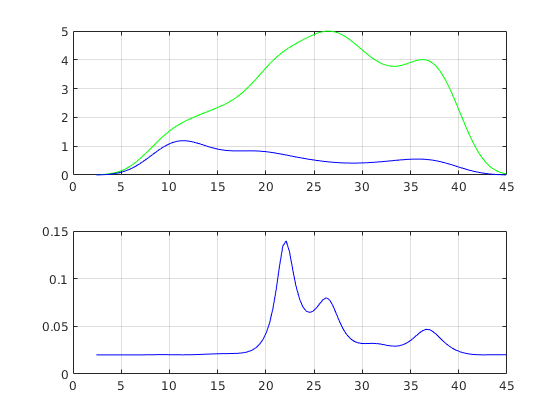



%data loading
data_raw_1 = load('/home/abrar/Desktop/research/SEED Dataset/Subject 8/Neg/8-1-7neg.mat');
data_raw_2 = load('/home/abrar/Desktop/research/SEED Dataset/Subject 1/Pos/1-3-14pos.mat');
data_raw_3 = load('/home/abrar/Desktop/research/SEED Dataset/Subject 1/Neu/1-3-13neu.mat');
data_1 = data_raw_1.ch;
data_2 = data_raw_2.ch;
data_3 = data_raw_3.ch;

channel = 23;
raw_data_1 = data_1(channel,:);
raw_data_2 = data_2(channel,:);
raw_data_3 = data_3(channel,:);

%initial values
Length_1 = length(raw_data_1);
Length_2 = length(raw_data_2);
Length_3 = length(raw_data_3);

F_sample = 200;
F_nquist = F_sample/ 2;
T_sample = 1/F_sample;

time_series_1 = (0:Length_1-1)*T_sample;
time_series_2 = (0:Length_2-1)*T_sample;
time_series_3 = (0:Length_3-1)*T_sample;

%notch filtering
notch_filter_50_hz = designfilt('bandstopiir','FilterOrder',2,'HalfPowerFrequency1',48,'HalfPowerFrequency2',52, ...
    'DesignMethod','butter','SampleRate',200);

notch_filtered_sig_1 = filtfilt(notch_filter_50_hz,raw_data_1);
notch_filtered_sig_2 = filtfilt(notch_filter_50_hz,raw_data_2);
notch_filtered_sig_3 = filtfilt(notch_filter_50_hz,raw_data_3);

%band pass
bp_500_filter_4_40 = fir1(500, [8,40]/100, 'bandpass');

signal_1 = filter(bp_500_filter_4_40,1,notch_filtered_sig_1);
signal_2 = filter(bp_500_filter_4_40,1,notch_filtered_sig_2);
signal_3 = filter(bp_500_filter_4_40,1,notch_filtered_sig_3);

%welch 579 dft spectrum
[welc_579_signal_1, f_579_signal_1] = ...
    pwelch(signal_1, 50, 25, 579, F_sample);
[welc_579_signal_2, f_579_signal_2] = ...
    pwelch(signal_2, 50, 25, 579, F_sample);
[welc_579_signal_3, f_579_signal_3] = ...
    pwelch(signal_3, 50, 25, 579, F_sample);

%selected 124 dft point band (2.4 hz to 45 hz)
welc_579_selected_124_signal_1 = welc_579_signal_1(8:131);
f_579_selected_124_signal_1 = f_579_signal_1(8:131);

welc_579_selected_124_signal_2 = welc_579_signal_2(8:131);
f_579_selected_124_signal_2 = f_579_signal_2(8:131);

welc_579_selected_124_signal_3 = welc_579_signal_3(8:131);
f_579_selected_124_signal_3 = f_579_signal_3(8:131);

%p=6, th = 1.1
[music_p_th_signal_1_579, f_p_th_signal_1_579] = ...
    pmusic(signal_1, [6,1.1], 579, F_sample, 50, 25);
[music_p_th_signal_2_579, f_p_th_signal_2_579] = ...
    pmusic(signal_2, [6,1.1], 579, F_sample, 50, 25);
[music_p_th_signal_3_579, f_p_th_signal_3_579] = ...
    pmusic(signal_3, [6,1.1], 579, F_sample, 50, 25);


%selected 124 dft point band (2.4 hz to 45 hz)
music_p_th_579_selected_signal_1 = music_p_th_signal_1_579(8:131);
f_p_th_579_selected_signal_1 = f_p_th_signal_1_579(8:131);

music_p_th_579_selected_signal_2 = music_p_th_signal_2_579(8:131);
f_p_th_579_selected_signal_2 = f_p_th_signal_2_579(8:131);

music_p_th_579_selected_signal_3 = music_p_th_signal_3_579(8:131);
f_p_th_579_selected_signal_3 = f_p_th_signal_3_579(8:131);



%automated
auto_1 = readtable('/home/abrar/Desktop/transformed_Seed/music/Subject 8/Neg/8-1-7neg_music.csv');
auto_2 = readtable('/home/abrar/Desktop/transformed_Seed/music/Subject 1/Pos/1-3-14pos_music.csv');
auto_3 = readtable('/home/abrar/Desktop/transformed_Seed/music/Subject 1/Neu/1-3-13neu_music.csv');


wel_1 = readtable('/home/abrar/Desktop/transformed_Seed/welch/Subject 1/Neg/1-3-15neg_welc.csv');
wel_2 = readtable('/home/abrar/Desktop/transformed_Seed/welch/Subject 1/Pos/1-3-14pos_welc.csv');
wel_3 = readtable('/home/abrar/Desktop/transformed_Seed/welch/Subject 1/Neu/1-3-13neu_welc.csv');

figure;
subplot(2,1,1)
plot(f_579_selected_124_signal_1, welc_579_selected_124_signal_1, 'g')
hold on
plot(wel_1.f,wel_1.ch_23,'b')
hold off
grid on

subplot(2,1,2)
plot(f_p_th_579_selected_signal_1, music_p_th_579_selected_signal_1, 'r')
hold on
plot(auto_1.f,auto_1.ch_23,'b')
hold off
grid on

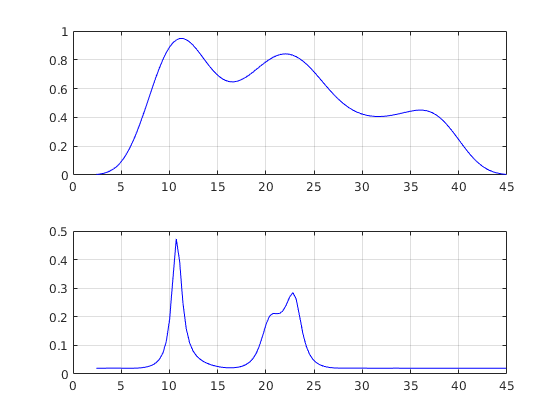


figure;
subplot(2,1,1)
plot(f_579_selected_124_signal_2, welc_579_selected_124_signal_2, 'g')
hold on
plot(wel_2.f,wel_2.ch_23,'b')
hold off
grid on

subplot(2,1,2)
plot(f_p_th_579_selected_signal_1, music_p_th_579_selected_signal_2, 'r')
hold on
plot(auto_2.f,auto_2.ch_23,'b')
hold off
grid on
grid on

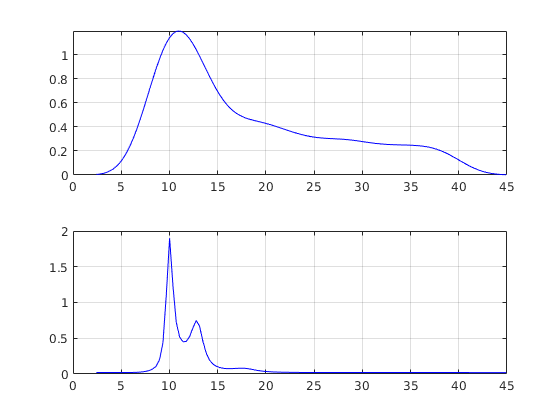


figure;
subplot(2,1,1)
plot(f_579_selected_124_signal_3, welc_579_selected_124_signal_3, 'g')
hold on
plot(wel_3.f,wel_3.ch_23,'b')
hold off
grid on

subplot(2,1,2)
plot(f_p_th_579_selected_signal_1, music_p_th_579_selected_signal_3, 'r')
hold on
plot(auto_3.f,auto_3.ch_23,'b')
hold off
grid on
grid on